# Funcion de Christoffel (primera forma fundamental)

La función de Matlab que me has proporcionado calcula los símbolos de Christoffel de segunda especie en un espacio métrico bidimensional. 

Los símbolos de Christoffel se presentan a continuación:

Veamos paso a paso lo que hace la función:

**Entrada:**

- `S`: Representa la métrica del espacio, definida como una función simbólica de dos variables `u` y `v`.

- `u` y `v`: Son las coordenadas del espacio.

**Salida:**

- `chr`: Tensor de símbolos de Christoffel de segunda especie (salida principal).

- `gg1`: Matriz de coeficientes métricos `[E, F; F, G]`.

- `gg2`: Matriz auxiliar `[L, M; M, N]`.

- `e`, `g`: Vectores base covariantes obtenidos mediante la derivada parcial de la métrica.

- `E`, `G`, `F`: Coeficientes métricos obtenidos a partir de los vectores base.

- `ev`, `eu`: Derivadas parciales de `E` respecto a `v` y `u`, respectivamente.

- `gv`, `gu`: Derivadas parciales de `G` respecto a `v` y `u`, respectivamente.

**Proceso:**

**            1)Primera Forma Fundamental:**

- Calcula los vectores base covariantes `e` y `g` a través de la derivada parcial de la métrica `S`.

                
$$e\;\;=\frac{\textrm{ds}}{\textrm{du}}\;$$


                
$$g\;=\frac{\textrm{ds}}{\textrm{dv}}\;$$


- Obtiene los coeficientes métricos `E1`, `G1`, y `F1` mediante el producto punto de los vectores base.

                
$$\textrm{E1}\;=\;S_u *S_u \;\;$$


                
$$\textrm{G1}\;=\;S_v *S_v \;$$


                
$$\textrm{F1}\;=\;S_u *S_v \;$$


- Obtiene los coeficientes métricos `E`, `G`, y `F` mediante `simplify, que` es una herramienta valiosa en MATLAB para simplificar expresiones simbólicas, haciéndolas más compactas y manejables sin alterar su significado matemático.

            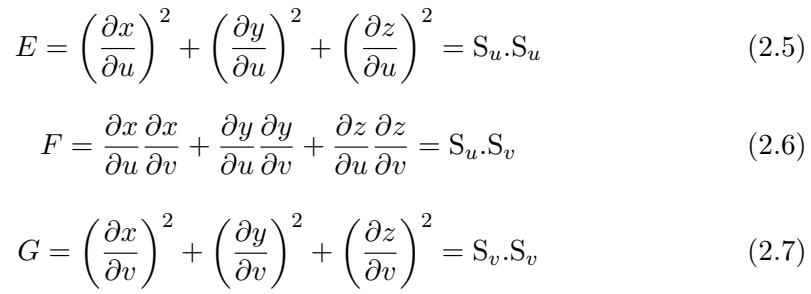

**            2) Vector Normal:**

- Define un vector normal `n` como el producto vectorial de `e` y `g` (cross) y además lo normaliza (norm).

            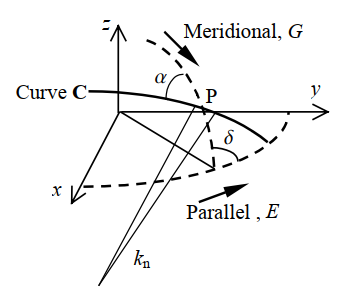

**            4) Segunda Forma Fundamental:**

- Calcula los coeficientes de conexión de Christoffel de segunda especie `L`, `M`, y `N` usando el vector normal `n` y las derivadas parciales de los vectores base.

         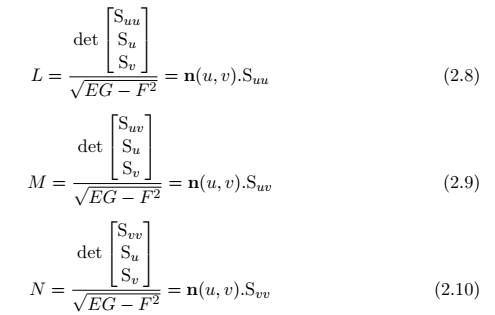

**            4) Derivadas de los Coeficientes Métricos:**

- Calcula las derivadas parciales de `E` y `G` respecto a `u` y `v` y las almacena en `ev`, `eu`, `gv`, y `gu`.

**            5) Símbolos de Christoffel:**

- La parte principal de la función calcula los símbolos de Christoffel de segunda especie `chr(i, j, k)` utilizando ecuaciones que involucran los coeficientes métricos, el vector normal, y sus derivadas parciales. Los coeficientes de Christoffel se calculan en base al trabajo de P. Blaga (Paul A. Blaga. "Lectures on Classical Differential Geometry". Editura Risoprint. 2005.)

        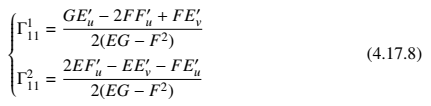

         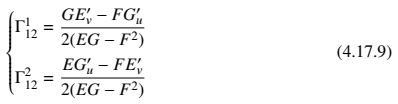

        

**Resumen:**

Esta función esencialmente calcula los símbolos de Christoffel de segunda especie a partir de una métrica bidimensional (superficie). Estos símbolos son fundamentales para estudiar las geodésicas y la curvatura en espacios curvos.

function coeficientes_de_Christoffel = funcion_de_Christoffel(S, u, v)
    % s = Ecuación de la forma de la superficie
    % u = Primer variable independeinte
    % v = Segunda variable independiente

    % Primera formula fundamental
    e = formula(diff(S, u));
    E1 = dot(e, e);
    E = simplify(E1);
    g = formula(diff(S, v));
    G1 = dot(g, g);
    G = simplify(G1);
    F1 = dot(g, e);
    F = simplify(F1);

    gg1(1, 1) = E;
    gg1(1, 2) = F;
    gg1(2, 1) = F;
    gg1(2, 2) = G;

    n = cross(e, g) / norm(cross(e, g));
    %Segunda formula fundamental
    L = dot(n, diff(e, u));
    M = dot(n, diff(e, v));
    N = dot(n, diff(g, v));

    gg2(1, 1) = L;
    gg2(1, 2) = M;
    gg2(2, 1) = M;
    gg2(2, 2) = N;

    %Derivadas
    ev = simplify(diff(E, v));
    eu = simplify(diff(E, u));
    gv = simplify(diff(G, v));
    gu = simplify(diff(G, u));

    %Símbolos Christoffel
    chr(1, 1, 1) = simplify((G * (diff(E, u)) - 2 * F * diff(F, u) + F * diff(E, v)) / (2 * (E * G - F ^ 2)));
    chr(1, 1, 2) = simplify((2 * E * (diff(F, u)) - E * diff(E, v) - F * diff(E, u)) / (2 * (E * G - F ^ 2)));
    chr(1, 2, 1) = simplify((G * (diff(E, v)) - F * diff(G, u)) / (2 * (E * G - F ^ 2)));
    chr(2, 1, 1) = chr(1, 2, 1);
    chr(1, 2, 2) = simplify((E * (diff(G, u)) - F * diff(E, v)) / (2 * (E * G - F ^ 2)));
    chr(2, 1, 2) = chr(1, 2, 2);
    chr(2, 2, 1) = simplify((2 * G * (diff(F, v)) - G * diff(G, u) - F * diff(G, v)) / (2 * (E * G - F ^ 2)));
    chr(2, 2, 2) = simplify((E * (diff(G, v)) - 2 * F * diff(F, v) - F * diff(G, u)) / (2 * (E * G - F ^ 2)));

    coeficientes_de_Christoffel = struct( ...
        'chr', chr, ...
        'E', E, ...
        'F', F, ...
        'G', G, ...
        'gg1', gg1, ...
        'L', L, ...
        'M', M, ...
        'N', N, ...
        'gg2', gg2, ...
        'e', e, ...
        'g', g, ...
        'ev', ev, ...
        'eu', eu, ...
        'gv', gv, ...
        'gu', gu);
end